spettrogramma tono puro

Fs = 8000;
f0 = 3000;
t = 0:1/Fs:10;
N = 256;
L = 128

L = 128

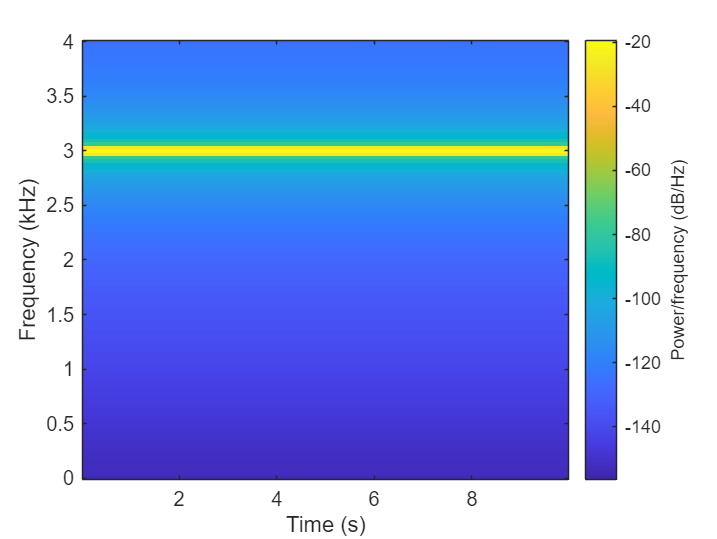

M = 256;
x = cos(2*pi*f0*t);
spectrogram(x,N,L,M,Fs,"yaxis")

Distorsione non lineare

Fs = 8000;
f0 = 700;
t = 0:1/Fs:10;
beta = linspace(0,1,length(t));
x = cos(2*pi*f0*t);
y = tanh(beta.*x);
subplot(121)
spectrogram(x,256,128,256,Fs,"yaxis")
subplot(122)
spectrogram(y,256,128,256,Fs,"yaxis")

L’aliasing

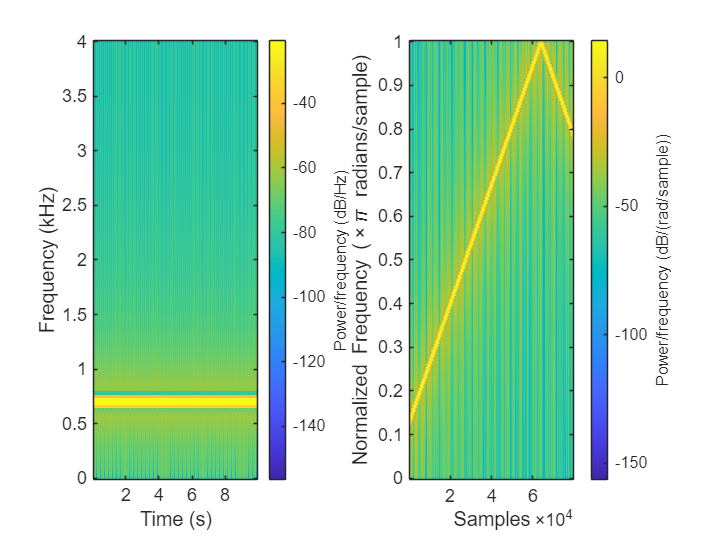

Fs = 8000;
t = 0:1/Fs:10;
x = chirp(t,500,8,4000);
spectrogram(x,256,128,256,"yaxis")

Spettrogramma del file audio

[x,Fs] = audioread("lathe.wav");
% soundsc(x,Fs)
% spectrogram(x,512,384,512,Fs,"yaxis")
% text(0.176,3.688,0,"a lathe is a big tool" + ... 
%     "          grab every dish of sugar", ... 
%     "FontSize",15)
% figure (2)
% plot((0:length(x)-1)/Fs,x)
% text(0.176,0.5,0,"a lathe is a big tool" + ... 
%     "          grab every dish of sugar", ... 
%     "FontSize",15)
signalAnalyzer(x,"samplerate",Fs)